**Load data**

addpath(genpath(pwd));

load battledata.mat

TQ = InflowData1.DatetimeCETCESTDDMMYYYYHHmm;
Q = table2array(InflowData1(:,2:11));
TW = WeatherData1.DatetimeCETCESTDDMMYYYYHHmm;
W = table2array(WeatherData1(:,2:5));


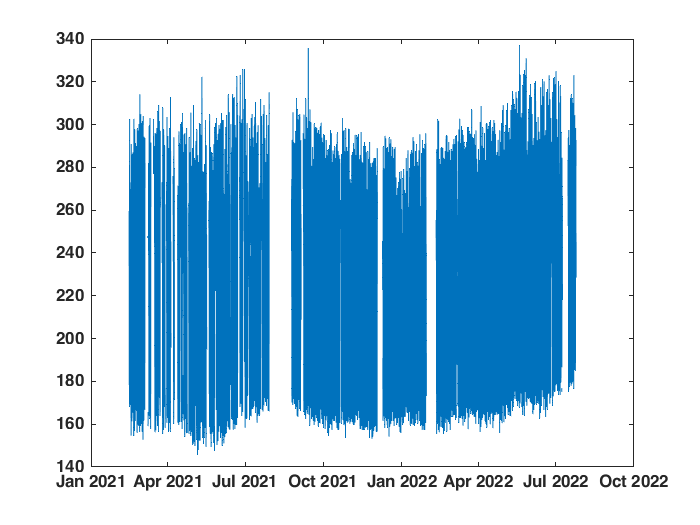

% Plot total of all values to estimate seasonality
SumQ = sum(Q,2);
figure
plot(TQ,SumQ)

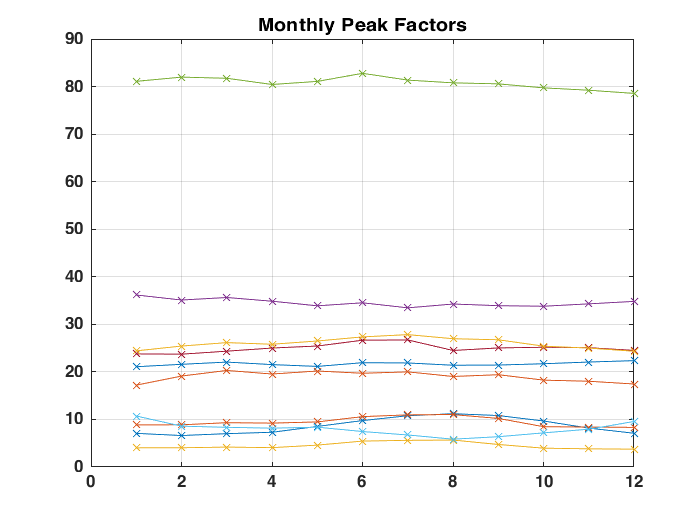

% Convert the datetime to proper format if it's not already
dt = datetime(TQ, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss');

% Preallocate the peak factor arrays
pfMonthly = zeros(12, size(Q, 2));  % 12 months
pfDaily = zeros(7, size(Q, 2));     % 7 days of the week
pfHourly = zeros(24, size(Q, 2));   % 24 hours

% Calculate Monthly Peak Factors
for months = 1:12
    for dma = 1:size(Q, 2)
        monthlyData = Q(month(dt) == months, dma);
        pfMonthly(months, dma) = nanmedian(monthlyData);  % Compute mean excluding NaNs
    end
end
%pfMonthly = pfMonthlyA./mean(pfMonthlyA);

% Calculate Daily Peak Factors
Q2 = Q./pfMonthly(month(dt),:);
for days = 1:7
    for dma = 1:size(Q2, 2)
        dailyData = Q2(day(dt, 'dayofweek') == days, dma);
        pfDaily(days, dma) = nanmedian(dailyData);  % Compute mean excluding NaNs
    end
end

% Calculate Hourly Peak Factors
Q3 = Q2./pfDaily(day(dt, 'dayofweek'),:);
for hours = 1:24
    for dma = 1:size(Q3, 2)
        hourlyData = Q3(hour(dt) == hours-1, dma);  % -1 because MATLAB hours are 0-23
        pfHourly(hours, dma) = nanmedian(hourlyData);  % Compute mean excluding NaNs
    end
end

% Output the peak factors
figure
plot(pfMonthly,'-x')
grid on
title('Monthly Peak Factors')

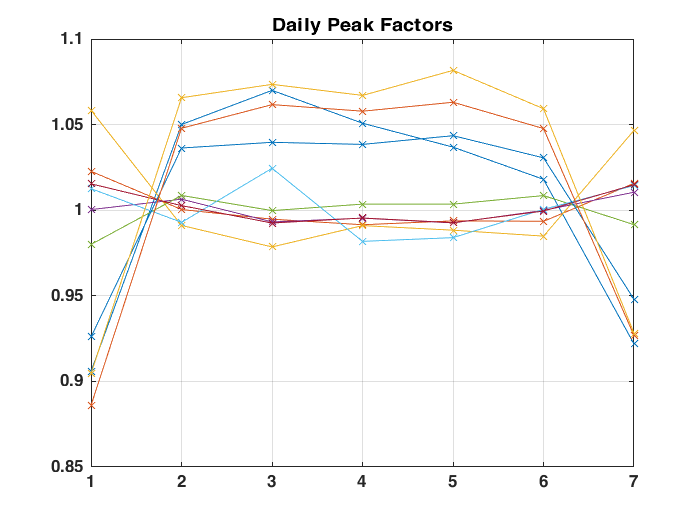

figure
plot(pfDaily,'-x')
grid on
title('Daily Peak Factors')

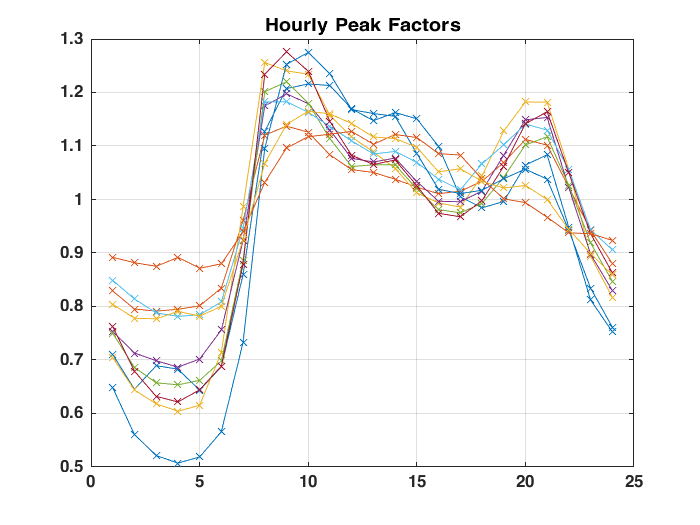

figure
plot(pfHourly,'-x')
grid on
title('Hourly Peak Factors')

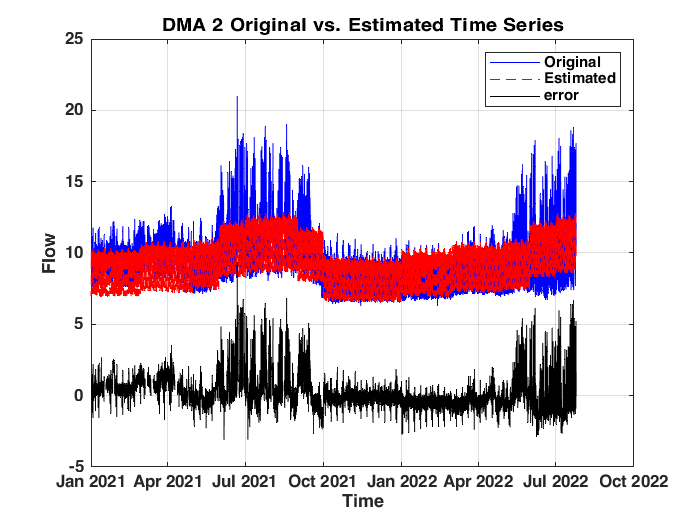

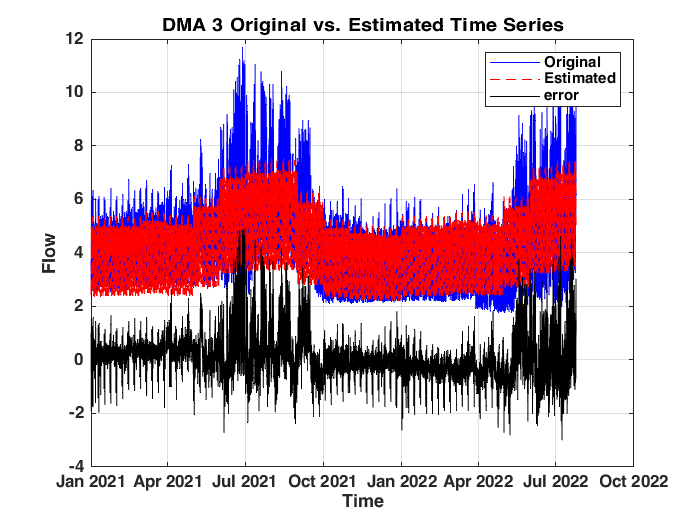

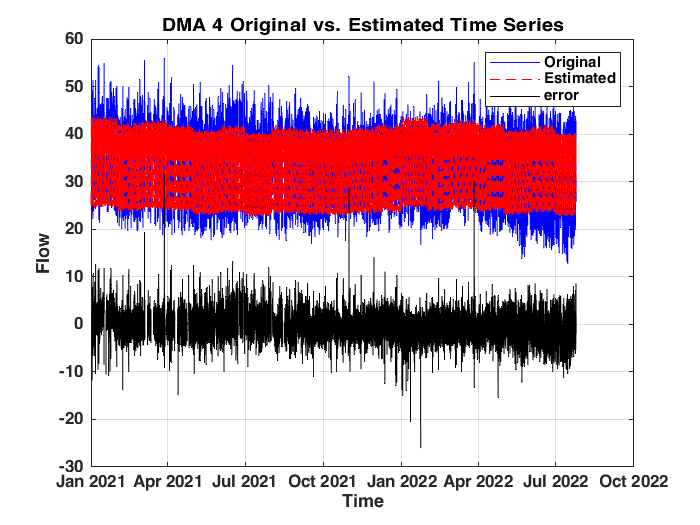

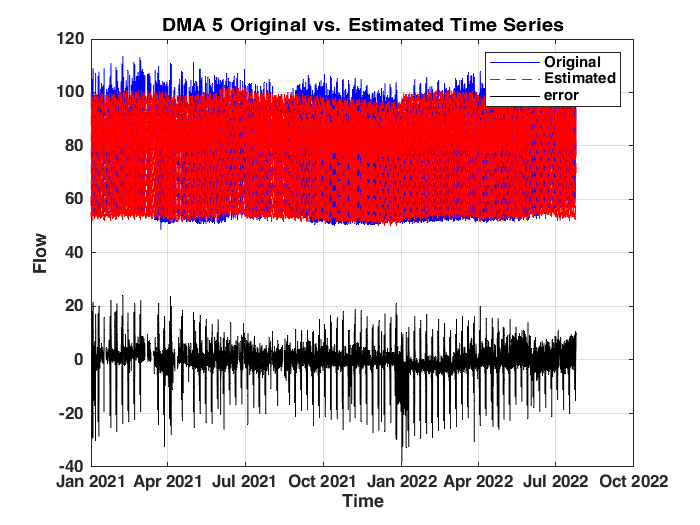

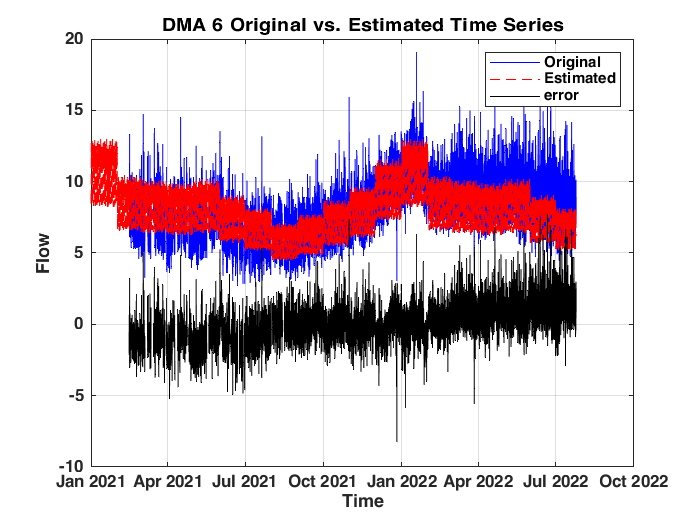

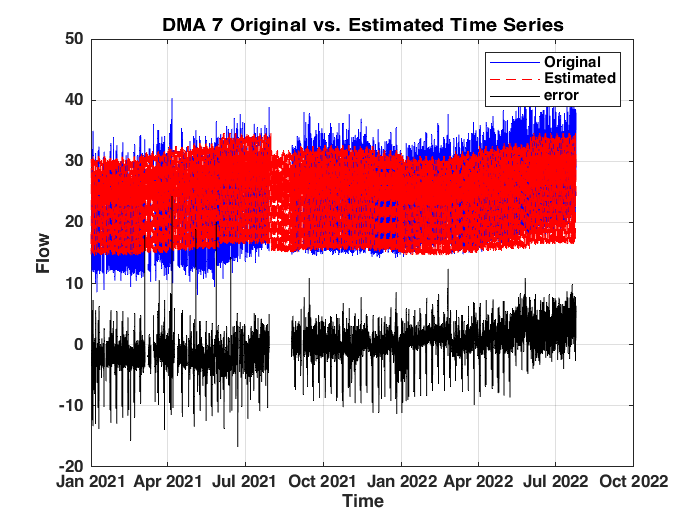

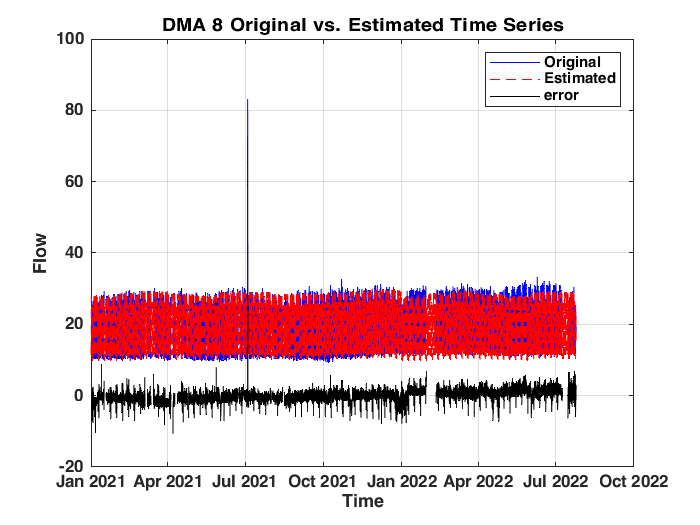

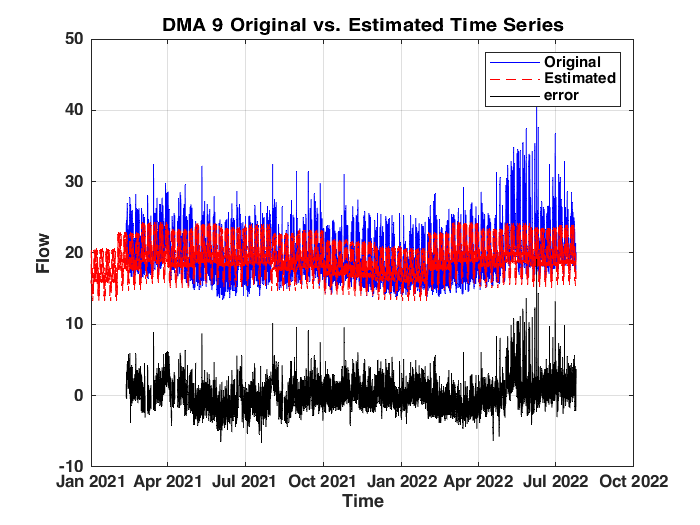

% Ensure you have the pfMonthly, pfDaily, and pfHourly from the previous step
% And Q is your original data, datetime is your array of datetime objects

% Preallocate the estimated matrix
Q_estimated = zeros(size(Q));

% Construct the estimated time series
for dma = 1:size(Q, 2)
    for t = 1:length(dt)
        months = month(dt(t));
        days = day(dt(t), 'dayofweek');
        hours = hour(dt(t));
        
        % Compute the estimated value
        Q_estimated(t, dma) = pfMonthly(months, dma) * pfDaily(days, dma) * pfHourly(hours+1, dma);
        %Q_estimated(t, dma) = pfHourly(hours+1, dma);
    end
end

% Plotting the original and estimated time series for each DMA
for dma = 1:size(Q, 2)
    figure; % Create a new figure for each DMA
    
    % Plotting the original data
    plot(dt, Q(:, dma), 'b', 'DisplayName', 'Original');
    hold on; % Hold on to plot the estimated data on the same figure
    
    % Plotting the estimated data
    plot(dt, Q_estimated(:, dma), 'r--', 'DisplayName', 'Estimated');
    
    err(:,dma) = Q(:, dma)-Q_estimated(:, dma);

    plot(dt, err(:,dma) ,'k-', 'DisplayName', 'error');
    % Adding title and labels
    title(['DMA ' num2str(dma) ' Original vs. Estimated Time Series']);
    xlabel('Time');
    ylabel('Flow');
    legend show;
    
    % Add grid for better readability
    grid on;
end

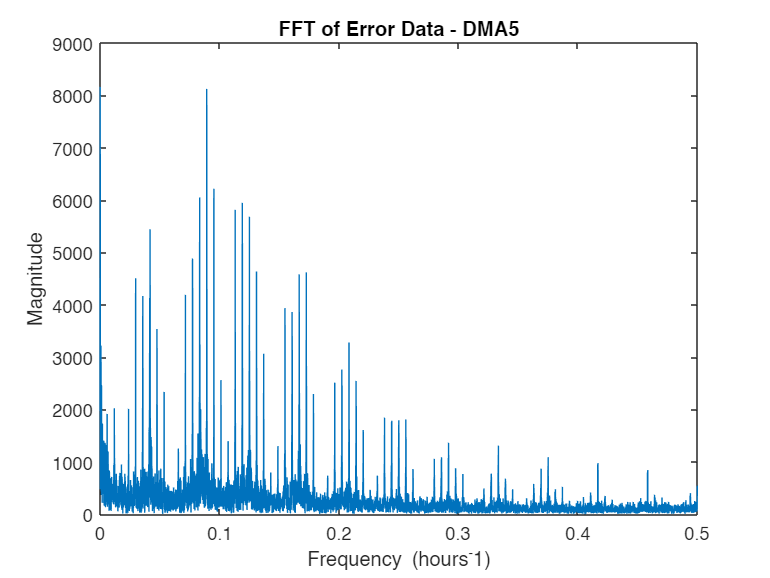

for ii = 1:10
    errorData = err(:,ii);
    errorData(isnan(errorData)) = 0;
    
    % Preallocate a matrix to hold the FFT results
    fftResults = zeros(size(errorData));
    
    % Apply FFT to each time series in the error data
    for i = 1:size(errorData, 2)
        fftResults(:, i) = fft(errorData(:, i));
    end
    
    % Compute the magnitude (absolute value) of the FFT results
    fftMag = abs(fftResults);
    
    % Assuming hourly data
    Fs = 1;  % Sampling frequency in hours^-1
    N = size(errorData, 1);  % Number of data points
    
    % Create a frequency axis
    f = (0:N-1)*(Fs/N);
    
    % Plotting the FFT results for the first time series as an example
    figure;
    plot(f, fftMag(:, 1));
    title(['FFT of Error Data - DMA', num2str(ii)]);
    xlabel('Frequency (hours^-1)');
    ylabel('Magnitude');
    
    % Since FFT results are symmetric, you only need to plot the first half for real signals
    xlim([0 Fs/2]);
end

% Assuming errorData is your matrix of estimation errors
% Each column corresponds to a DMA
errorData = err

errorData =        NaN       NaN    0.9018       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN    1.0042       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN    0.8172       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN    0.4398       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN    0.2901       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN   -0.1188       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN   -1.0502       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN   -1.9152       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN   -1.0608       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN   -0.0804       NaN       NaN       NaN       NaN       Na

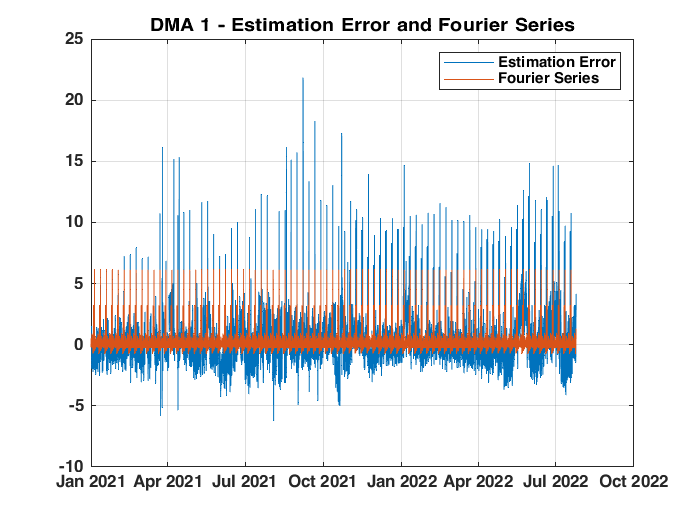

FourierTerms = 100; % Number of Fourier terms to include
w = 2 * pi/(7*24); % Fundamental frequency for annual periodicity

% Preallocate array for Fourier results
f4_all = zeros(size(errorData, 1)*2, size(errorData, 2));
MeanValue_all = zeros(1, size(errorData, 2));

% Loop over each DMA
for dma = 1:size(errorData, 2)
    % Extract the error data for the current DMA
    FDW = errorData(:, dma);
    
    % Remove NaNs for this analysis
    incl = ~isnan(FDW);
    KDW = find(incl);
    FDW = FDW(incl);
    
    % Compute the regression coefficients
    A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
    rcoef = A1\FDW; % Solving for the coefficients
    
    % Prepare the matrix for the full time series
    K2 = (1:(1*size(errorData, 1)))';
    A0 = [ones(length(K2),1) cos((1:FourierTerms)'*w*(K2'))' sin((1:FourierTerms)'*w*(K2'))'];
    T2 = datetime(2021,01,01,0:(length(K2)-1),0,0)';
    
    % Compute the Fourier series
    f4 = A0*rcoef;
    %f4_all(:, dma) = f4;
    
    % Compute the mean value of the original data over the Fourier series
    MeanValue_all(dma) = nanmean(errorData(:, dma) ./ f4(1:length(errorData)));
    
    % Plot the original data and the Fourier series
    figure;
    plot(dt, errorData(:, dma));
    hold on;
    plot(T2, f4);
    title(['DMA ' num2str(dma) ' - Estimation Error and Fourier Series']);
    legend('Estimation Error', 'Fourier Series');
    grid on;
    hold off;
    
    % Plot the ratio of the original data to the Fourier series
    figure;
    plot(dt, errorData(:, dma) ./ f4(1:length(errorData)));
    title(['DMA ' num2str(dma) ' - Ratio of Estimation Error to Fourier Series']);
    xlabel('Time');
    ylabel('Ratio');
    grid on;
end


% Display mean values for all DMAs
disp('Mean Values for all DMAs:');
disp(MeanValue_all);

K = (1:size(Q,1))'

SQ = sum(Q,2)
size(SQ)
size(T)

Plot

figure
plot(T, Q./nanmedian(Q))

figure
plot(T,SQ)


incl = ~isnan(SQ)
KD = K(incl);
FD = SQ(incl)/nanmedian(SQ);

Seasonality term

FourierTerms = 2;
w = 2 * pi/(365*24);
KDW = K(incl);
FDW = SQ(incl);

A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
rcoef = A1\FDW

K2 = (1:(2*size(Q,1)))'
A0 = [ones(length(K2),1) cos((1:FourierTerms)'*w*(K2'))' sin((1:FourierTerms)'*w*(K2'))'];
T2 = datetime(2021,01,01,0:(length(K2)-1),0,0)';

f4 = A0*rcoef;

figure
plot(T,SQ)
hold on
plot(T2,f4)
grid on

figure
plot(SQ./f4)
MeanValue = nanmean(SQ./f4)
grid on

FourierTerms = 100;
w = 2 * pi/(24*7);
KDW = K(incl);
FDW = SQ(incl);
A0 = [ones(length(K),1) cos((1:FourierTerms)'*w*(K'))' sin((1:FourierTerms)'*w*(K'))'];

A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
rcoef = A1\FDW

f4 = A0*rcoef;

figure
plot(SQ)
hold on
plot(f4)
grid on

Forecast next week

KF = (13681:(13681+24*7))'
A2 = [ones(length(KF),1) cos((1:FourierTerms)'*w*(KF'))' sin((1:FourierTerms)'*w*(KF'))'];
% forecast 
f5 = A2*rcoef;

hold on
plot(KF,f5)
grid on